% setting
folder = 'C:\Users\bear\Desktop\figure 4';  
tempname = 'liver_temp.csv';
filename = 'liver.csv';
outname = 'liver_final.csv';
imagename = 'matlab_mode';
imageout = 'highlight_polyploidy';
extension = '.tif';
num_channel = 4;

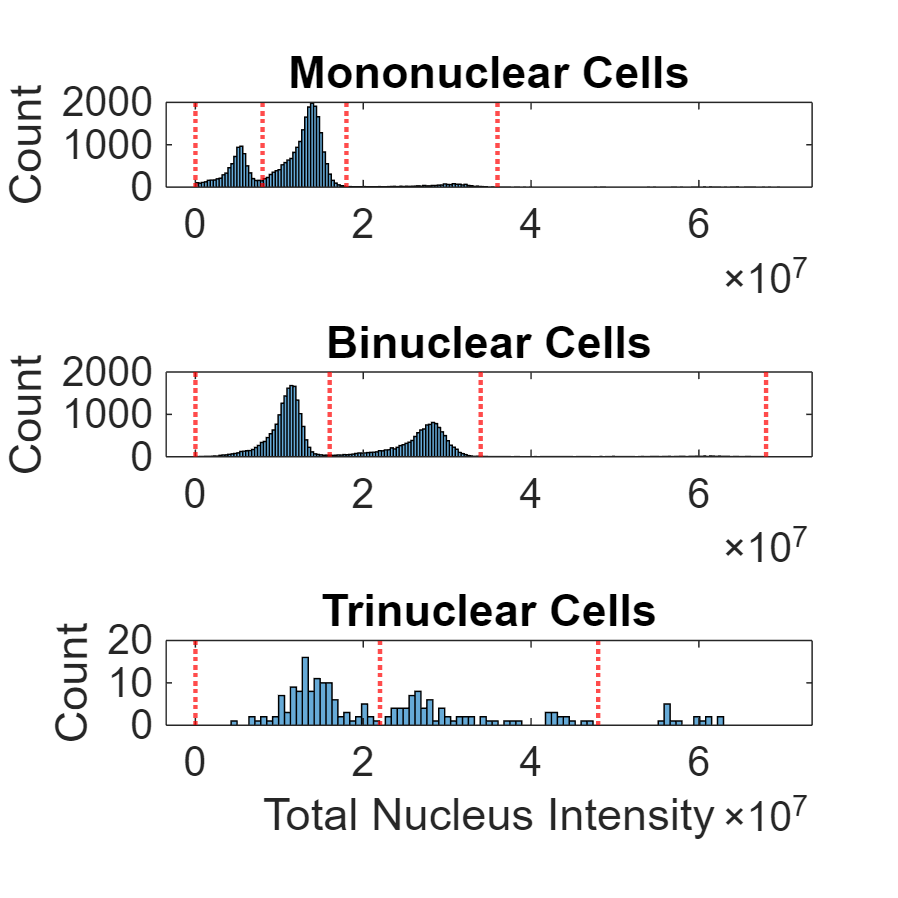

table = readtable(fullfile(folder, filename));
threshold_m = [0e6, 8e6, 18e6, 36e6];
threshold_b = [0e6, 16e6, 34e6, 68e6];
threshold_t = [0e6, 22e6, 48e6];

figure('Position', [100, 100, 600, 600]);
fontsize = 14;

% Define bins for mono/binuclear
all_intensities = table.TotalNucleusIntensity;
nbins = 200;  
edges = linspace(min(all_intensities), 7e7, nbins);

% Define same / fewer bins for multinuclear
nbins_tri = 100;  
edges_tri = linspace(min(all_intensities), 7e7, nbins_tri);

% Plot in three separate subplots
subplot(3,1,1)
histogram(table.TotalNucleusIntensity(table.NumNuclei == 1), edges)
title('Mononuclear Cells')
ylabel('Count')
hold on
for i = 1:length(threshold_m)
    xline(threshold_m(i), ':', 'Color', 'r', 'LineWidth', 1.5)
end
hold off
set(gca, 'FontSize', fontsize);

subplot(3,1,2)
histogram(table.TotalNucleusIntensity(table.NumNuclei == 2), edges)
title('Binuclear Cells')
ylabel('Count')
hold on
for i = 1:length(threshold_b)
    xline(threshold_b(i), ':', 'Color', 'r', 'LineWidth', 1.5)
end
hold off
set(gca, 'FontSize', fontsize);

subplot(3,1,3)
histogram(table.TotalNucleusIntensity(table.NumNuclei == 3), edges_tri)
title('Trinuclear Cells')
xlabel('Total Nucleus Intensity')
ylabel('Count')
hold on
for i = 1:length(threshold_t)
    xline(threshold_t(i), ':', 'Color', 'r', 'LineWidth', 1.5)
end
hold off
set(gca, 'FontSize', fontsize);

saveas(gcf, fullfile(folder, 'polyploidy.png'));

% Create new column as categorical
table = readtable(fullfile(folder, filename));
table.NuclearPloidy = strings(height(table), 1);
table.PloidyNuclear = strings(height(table), 1);

% For mononuclear cells
mono_idx = table.NumNuclei == 1;
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity < threshold_m(1)) = 'small';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(1) & table.TotalNucleusIntensity < threshold_m(2)) = 'm2n';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(2) & table.TotalNucleusIntensity < threshold_m(3)) = 'm4n';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(3) & table.TotalNucleusIntensity < threshold_m(4)) = 'm8n';
table.NuclearPloidy(mono_idx & table.TotalNucleusIntensity >= threshold_m(4)) = 'm16n';

% For binuclear cells
bi_idx = table.NumNuclei == 2;
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity < threshold_b(1)) = 'small';
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity >= threshold_b(1) & table.TotalNucleusIntensity < threshold_b(2)) = 'b2n';
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity >= threshold_b(2) & table.TotalNucleusIntensity < threshold_b(3)) = 'b4n';
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity >= threshold_b(3) & table.TotalNucleusIntensity < threshold_b(4)) = 'b8n';
table.NuclearPloidy(bi_idx & table.TotalNucleusIntensity >= threshold_b(4)) = 'b16n';

% For trinuclear cells
tri_idx = table.NumNuclei == 3;
table.NuclearPloidy(tri_idx & table.TotalNucleusIntensity < threshold_t(1)) = 'small';
table.NuclearPloidy(tri_idx & table.TotalNucleusIntensity >= threshold_t(1) & table.TotalNucleusIntensity < threshold_t(2)) = 't2n';
table.NuclearPloidy(tri_idx & table.TotalNucleusIntensity >= threshold_t(2) & table.TotalNucleusIntensity < threshold_t(3)) = 't4n';
table.NuclearPloidy(tri_idx & table.TotalNucleusIntensity >= threshold_t(3)) = 't8n';

% For tetranuclear cells
tetra_idx = table.NumNuclei >= 4;
table.NuclearPloidy(tetra_idx) = 'ttetra';

% set nuclear polyploidy
table.PloidyNuclear = extractAfter(table.NuclearPloidy, 1);
table.NuclearPloidy(tetra_idx) = 'tetra';

% Define the desired order for each nuclear type
total_cells = height(table);
fprintf('Total: %d', total_cells);

Total: 60558


mono_order = {'small', 'm2n', 'm4n', 'm8n', 'm16n'};
mono_data = table.NuclearPloidy(table.NumNuclei == 1);
mono_total = length(mono_data);
fprintf('Mononuclear: %d (%.1f%% of all cells)', mono_total, 100 * mono_total / total_cells);

Mononuclear: 30081 (49.7% of all cells)

for cat = mono_order
    count = sum(mono_data == cat{1});
    percent_category = 100 * count / mono_total;
    percent_total = 100 * count / total_cells;
    fprintf('%s: %d (%.1f%% of mono, %.1f%% of total)\n', cat{1}, count, percent_category, percent_total);
end

small: 0 (0.0% of mono, 0.0% of total)
m2n: 7821 (26.0% of mono, 12.9% of total)
m4n: 20927 (69.6% of mono, 34.6% of total)
m8n: 1269 (4.2% of mono, 2.1% of total)
m16n: 64 (0.2% of mono, 0.1% of total)



bi_order = {'small', 'b2n', 'b4n', 'b8n', 'b16n'};
bi_data = table.NuclearPloidy(table.NumNuclei == 2);
bi_total = length(bi_data);
fprintf('Binuclear: %d (%.1f%% of all cells)', bi_total, 100 * bi_total / total_cells);

Binuclear: 30245 (49.9% of all cells)

for cat = bi_order
    count = sum(bi_data == cat{1});
    percent_category = 100 * count / bi_total;
    percent_total = 100 * count / total_cells;
    fprintf('%s: %d (%.1f%% of bi, %.1f%% of total)\n', cat{1}, count, percent_category, percent_total);
end

small: 0 (0.0% of bi, 0.0% of total)
b2n: 17435 (57.6% of bi, 28.8% of total)
b4n: 12474 (41.2% of bi, 20.6% of total)
b8n: 335 (1.1% of bi, 0.6% of total)
b16n: 1 (0.0% of bi, 0.0% of total)



tri_order = {'small', 't2n', 't4n', 't8n'};
tri_data = table.NuclearPloidy(table.NumNuclei == 3);
tri_total = length(tri_data);
fprintf('Trinuclear: %d (%.1f%% of all cells)', tri_total, 100 * tri_total / total_cells);

Trinuclear: 201 (0.3% of all cells)

for cat = tri_order
    count = sum(tri_data == cat{1});
    percent_category = 100 * count / tri_total;
    percent_total = 100 * count / total_cells;
    fprintf('%s: %d (%.1f%% of tri, %.1f%% of total)\n', cat{1}, count, percent_category, percent_total);
end

small: 0 (0.0% of tri, 0.0% of total)
t2n: 113 (56.2% of tri, 0.2% of total)
t4n: 73 (36.3% of tri, 0.1% of total)
t8n: 15 (7.5% of tri, 0.0% of total)



tetra_data = table.NuclearPloidy(table.NumNuclei == 4);
tetra_total = length(tetra_data);
fprintf('Tetranuclear: %d (%.2f%% of all cells)', tetra_total, 100 * tetra_total / total_cells);

Tetranuclear: 30 (0.05% of all cells)


writetable(table, fullfile(folder, outname));

% Initialize counters for each ploidy level
table = readtable(fullfile(folder, outname));
ploidy_2n = 0;
ploidy_4n = 0;
ploidy_8n = 0;
ploidy_16n = 0;
small = 0;

% Count mononuclear cells
mono_data = table.NuclearPloidy(table.NumNuclei == 1);
small = small + sum(strcmp(mono_data, 'small'));
ploidy_2n = ploidy_2n + sum(strcmp(mono_data, 'm2n'));
ploidy_4n = ploidy_4n + sum(strcmp(mono_data, 'm4n'));
ploidy_8n = ploidy_8n + sum(strcmp(mono_data, 'm8n'));
ploidy_16n = ploidy_16n + sum(strcmp(mono_data, 'm16n'));

% Count binuclear cells (each nucleus counts as half the total)
bi_data = table.NuclearPloidy(table.NumNuclei == 2);
small = small + 2 * sum(strcmp(bi_data, 'small'));
ploidy_2n = ploidy_2n + 2 * sum(strcmp(bi_data, 'b2n'));
ploidy_4n = ploidy_4n + 2 * sum(strcmp(bi_data, 'b4n'));
ploidy_8n = ploidy_8n + 2 * sum(strcmp(bi_data, 'b8n'));
ploidy_16n = ploidy_16n + 2 * sum(strcmp(bi_data, 'b16n'));

% Count trinuclear cells (each nucleus counts as one-third the total)
tri_data = table.NuclearPloidy(table.NumNuclei == 3);
small = small + 3 * sum(strcmp(tri_data, 'small'));
ploidy_2n = ploidy_2n + 3 * sum(strcmp(tri_data, 't2n'));
ploidy_4n = ploidy_4n + 3 * sum(strcmp(tri_data, 't4n'));
ploidy_8n = ploidy_8n + 3 * sum(strcmp(tri_data, 't8n')); % Counting >4n as 8n

% Count tetranuclear cells (each counted as 2n)
tetra_total = sum(table.NumNuclei == 4);
ploidy_2n = ploidy_2n + 4 * tetra_total;

% Calculate total nuclei
total_nuclei = small + ploidy_2n + ploidy_4n + ploidy_8n + ploidy_16n;

% Print results
fprintf('\nTotal nuclei count by ploidy:\n');


Total nuclei count by ploidy:


fprintf('Small nuclei: %d (%.1f%%)\n', small, 100 * small / total_nuclei);

Small nuclei: 0 (0.0%)


fprintf('2n nuclei: %d (%.1f%%)\n', ploidy_2n, 100 * ploidy_2n / total_nuclei);

2n nuclei: 43150 (47.3%)


fprintf('4n nuclei: %d (%.1f%%)\n', ploidy_4n, 100 * ploidy_4n / total_nuclei);

4n nuclei: 46094 (50.5%)


fprintf('8n nuclei: %d (%.1f%%)\n', ploidy_8n, 100 * ploidy_8n / total_nuclei);

8n nuclei: 1984 (2.2%)


fprintf('16n nuclei: %d (%.1f%%)\n', ploidy_16n, 100 * ploidy_16n / total_nuclei);

16n nuclei: 66 (0.1%)


fprintf('Total nuclei: %d\n', total_nuclei);

Total nuclei: 91294


% Create new column as categorical
table = readtable(fullfile(folder, outname));
table.NCRatio = table.TotalNucleusVolume ./ table.Volume;
writetable(table, fullfile(folder, outname));

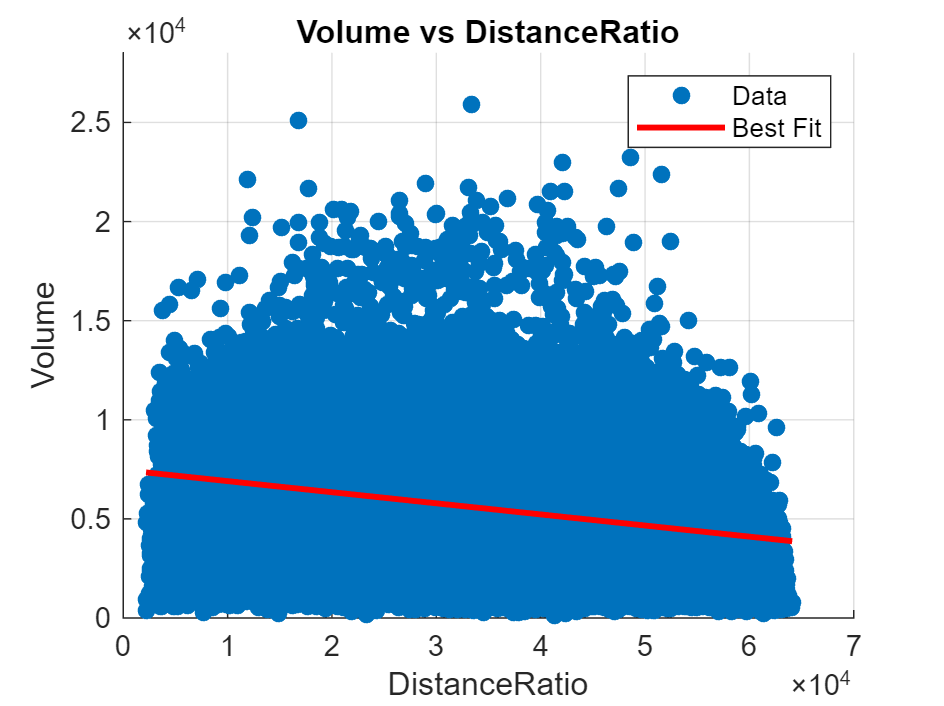

% ID, DistanceRatio, Volume, eccentricity
% TotalNucleusVolume, TotalNucleusIntensity, NumNuclei, NuclearPloidy
% PloidyNuclear, NCRatio
table = readtable(fullfile(folder, outname));
% table = table(table.NumNuclei == 1, :);
% table = table(table.NuclearPloidy ~= "small", :);

% Continuous variables
columns1 = [3, 2];
plot_scatter(table, columns1);

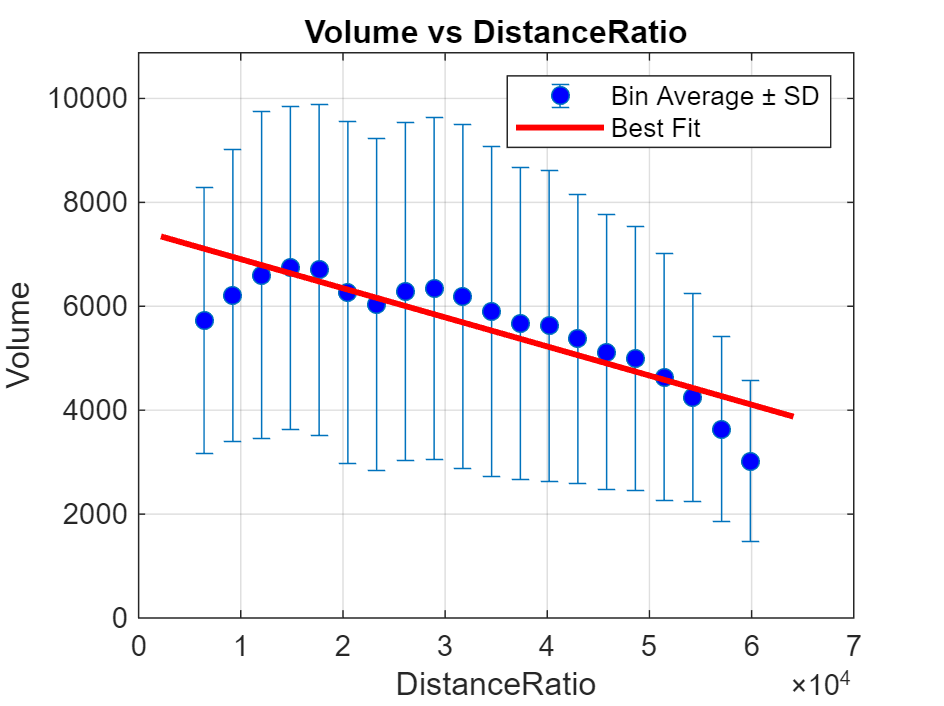

plot_error_bars(table, columns1, 20);
saveas(gcf, 'cell volume.png')

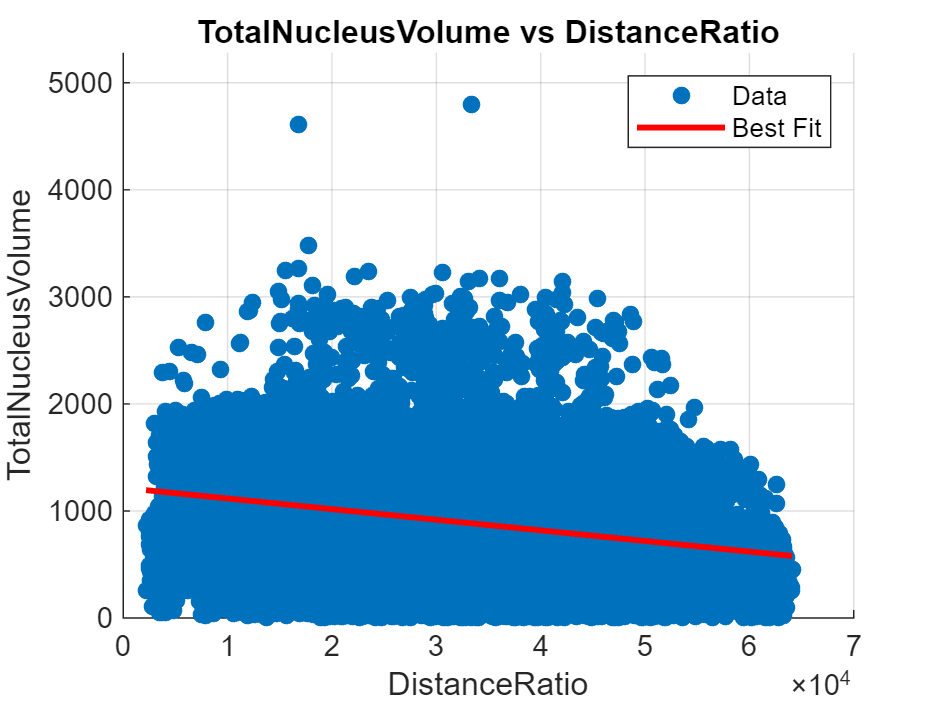


columns1 = [5, 2];
plot_scatter(table, columns1);

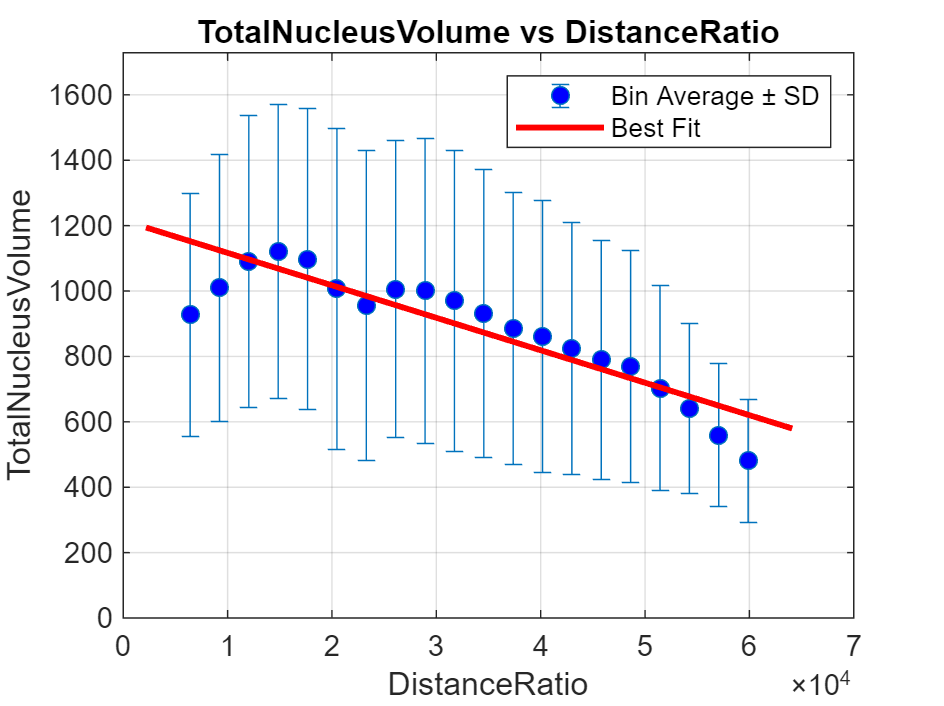

plot_error_bars(table, columns1, 20);
saveas(gcf, 'nuclear volume.png')

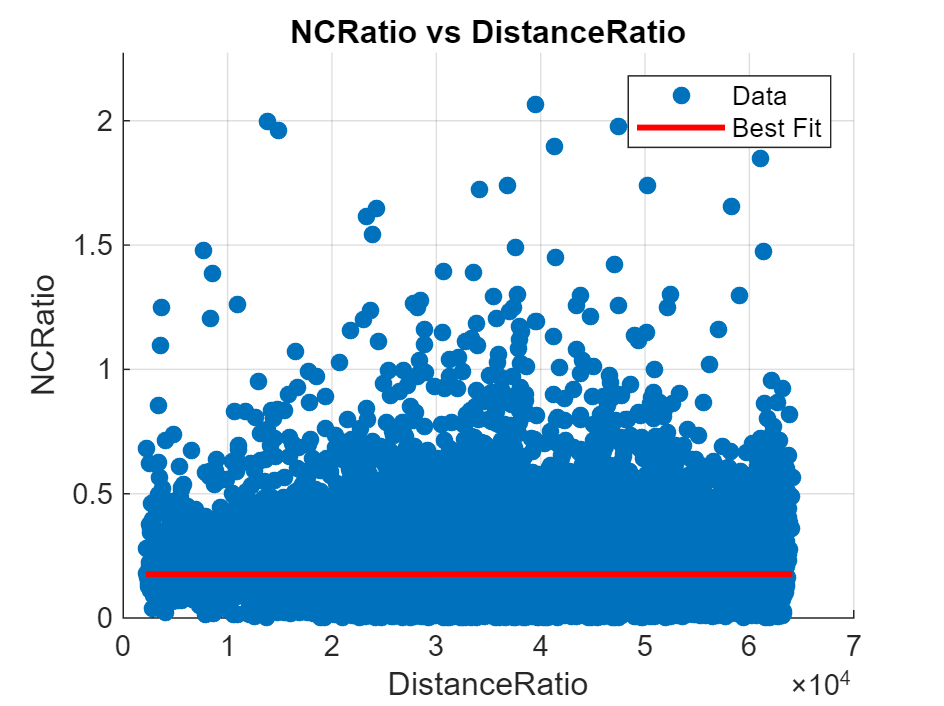


columns1 = [10, 2];
plot_scatter(table, columns1);

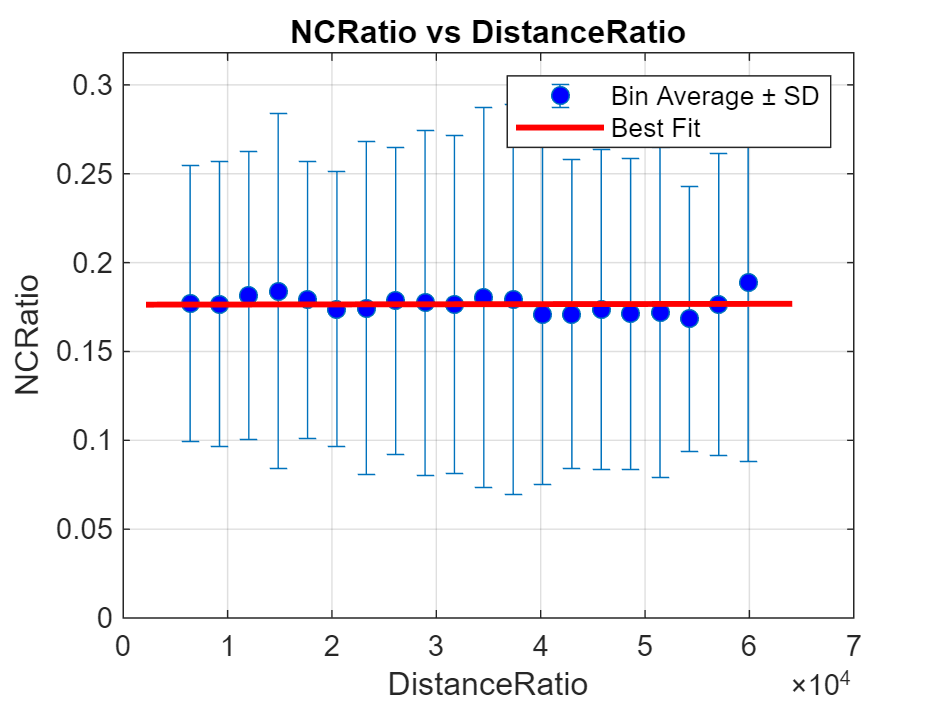

plot_error_bars(table, columns1, 20);
saveas(gcf, 'NC ratio.png')

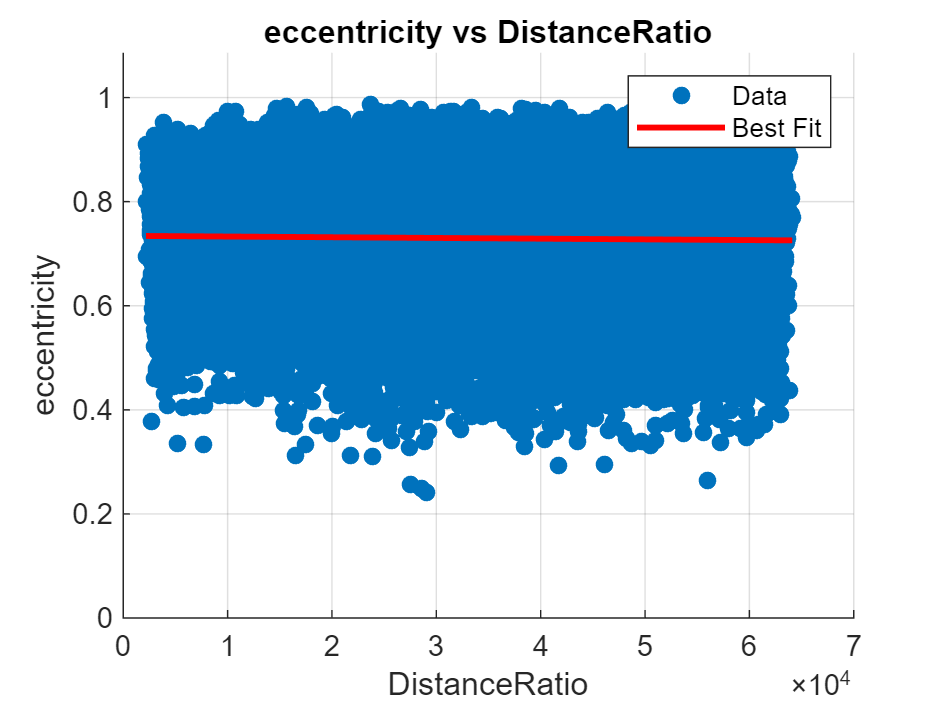


columns1 = [4, 2];
plot_scatter(table, columns1);

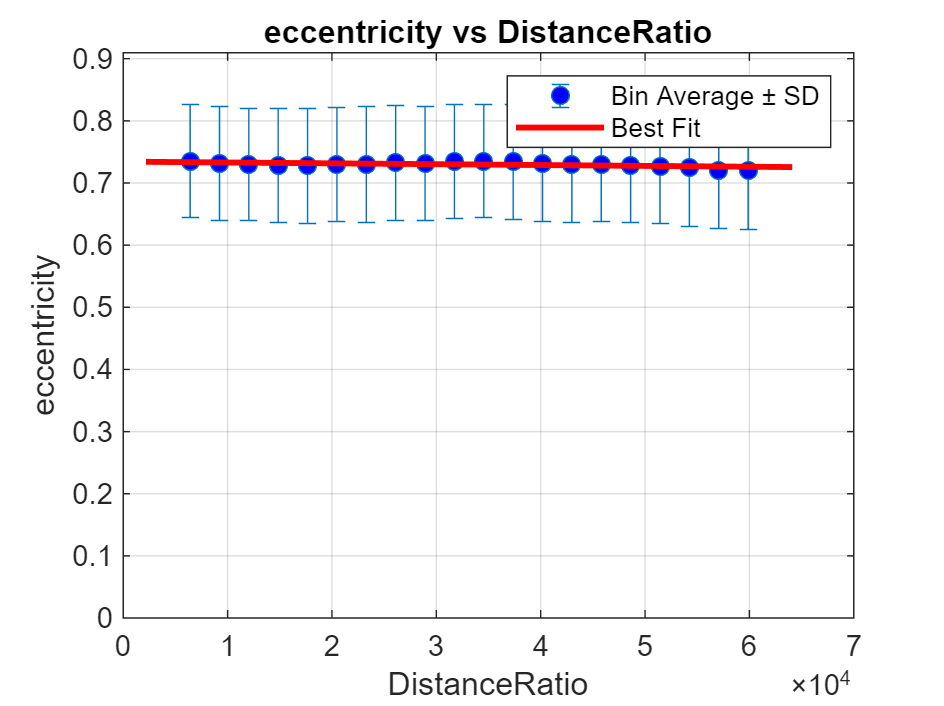

plot_error_bars(table, columns1, 20);
saveas(gcf, 'eccentricity.png')

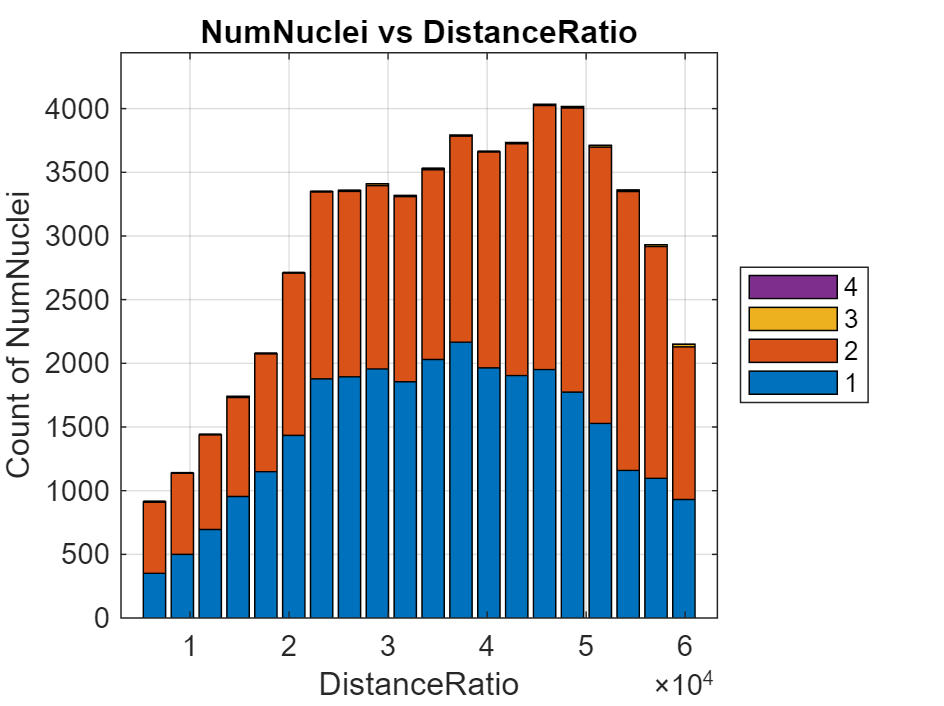

% another trial
table = readtable(fullfile(folder, outname));
table = table(table.NumNuclei <= 4, :);

% Categorical variables
columns2 = [7, 2];
plot_stacked_counts(table, columns2, 20);

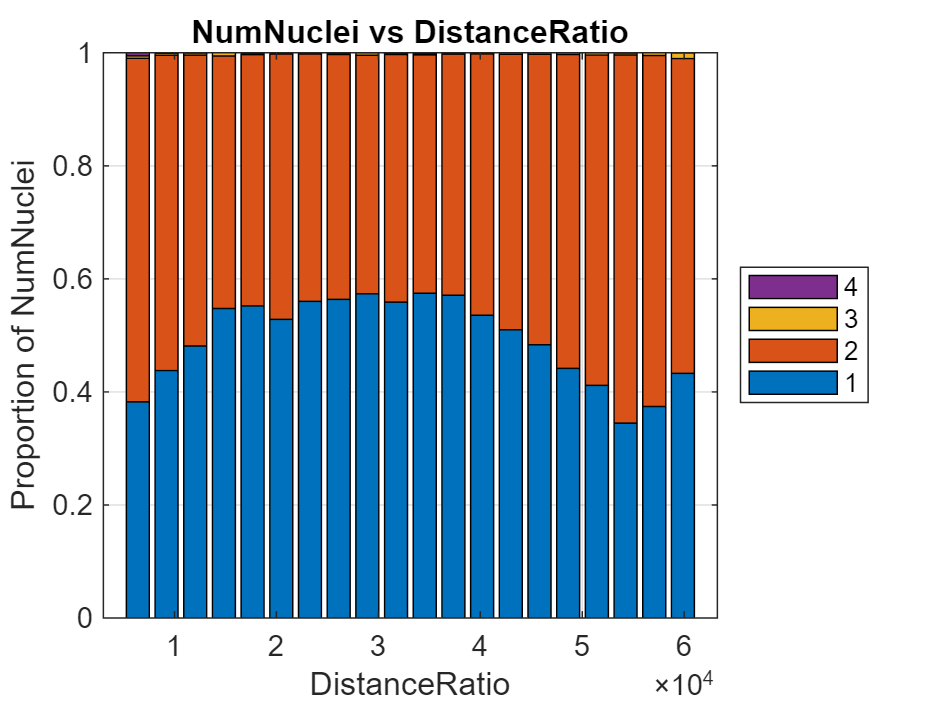

plot_stacked_proportions(table, columns2, 20);
saveas(gcf, 'cellular ploidy.png')

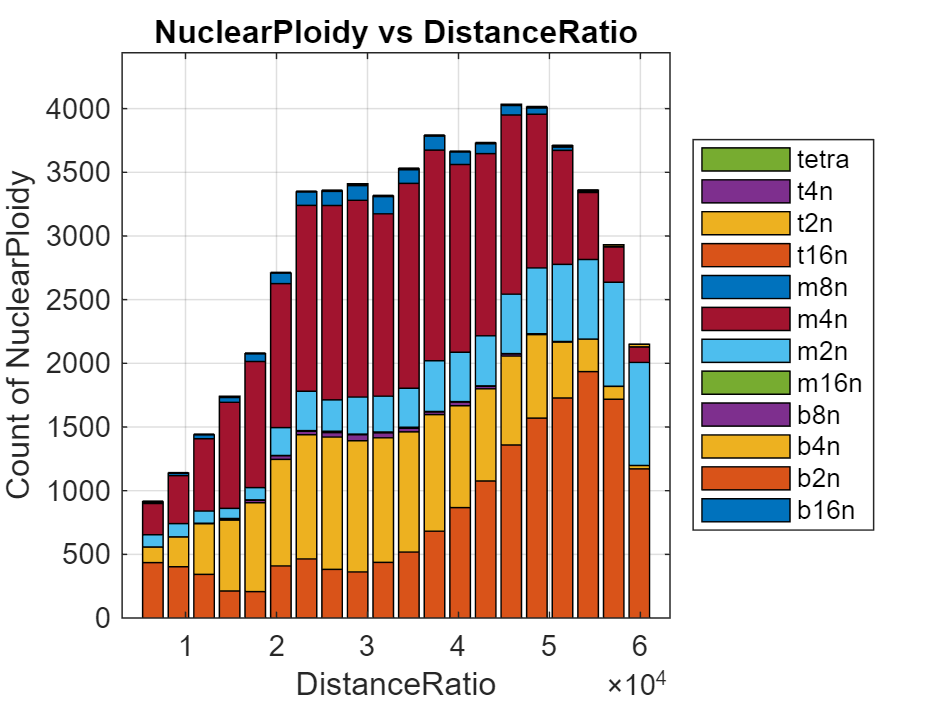


columns2 = [8, 2];
plot_stacked_counts(table, columns2, 20);

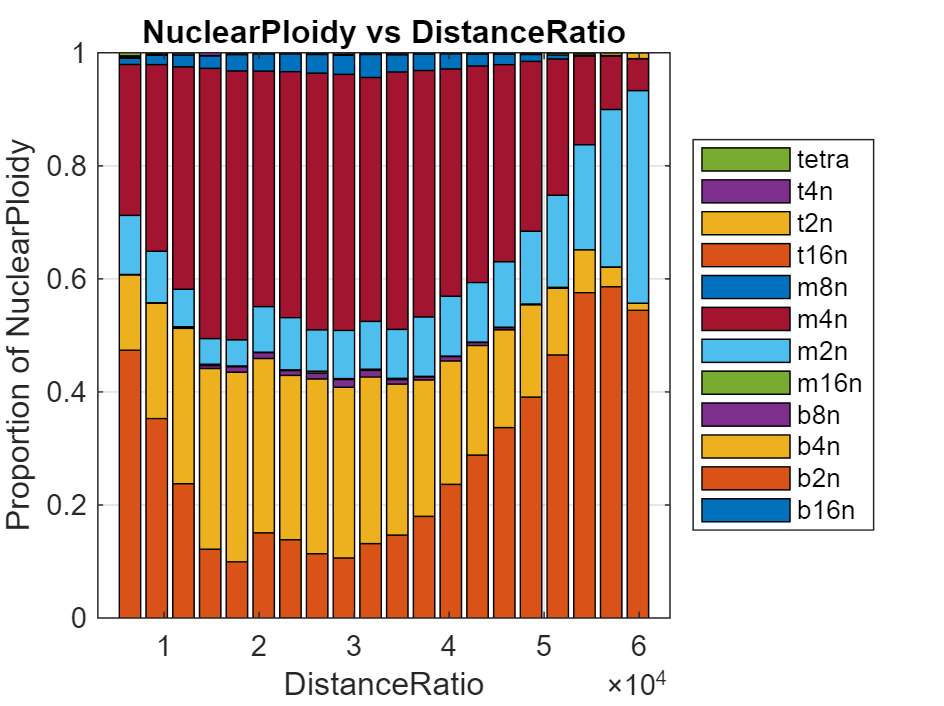

plot_stacked_proportions(table, columns2, 20);
saveas(gcf, 'all ploidy.png')

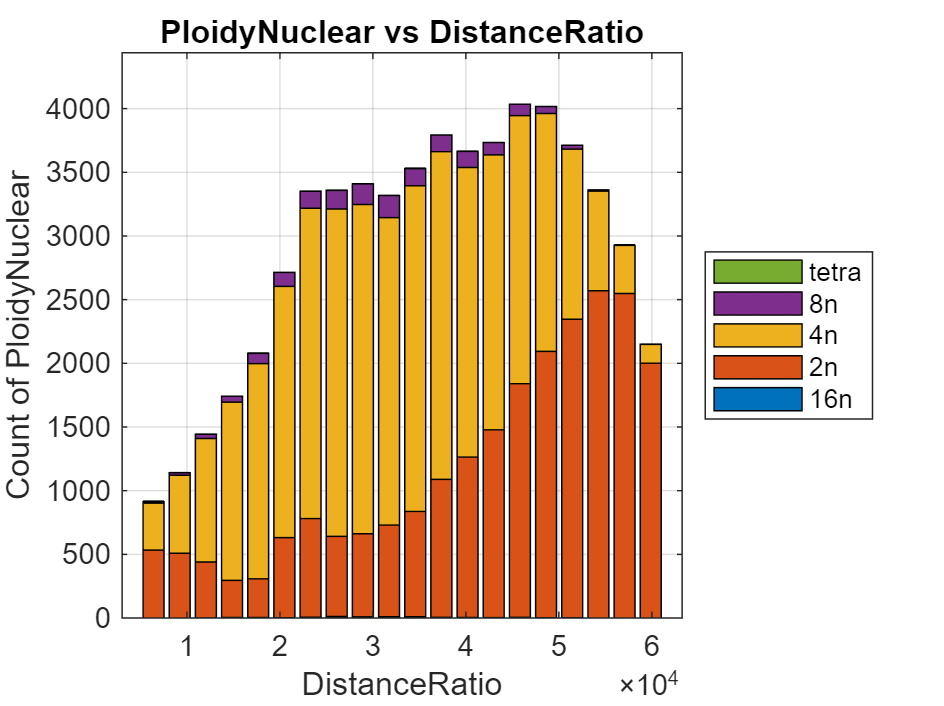


columns2 = [9, 2];
plot_stacked_counts(table, columns2, 20);

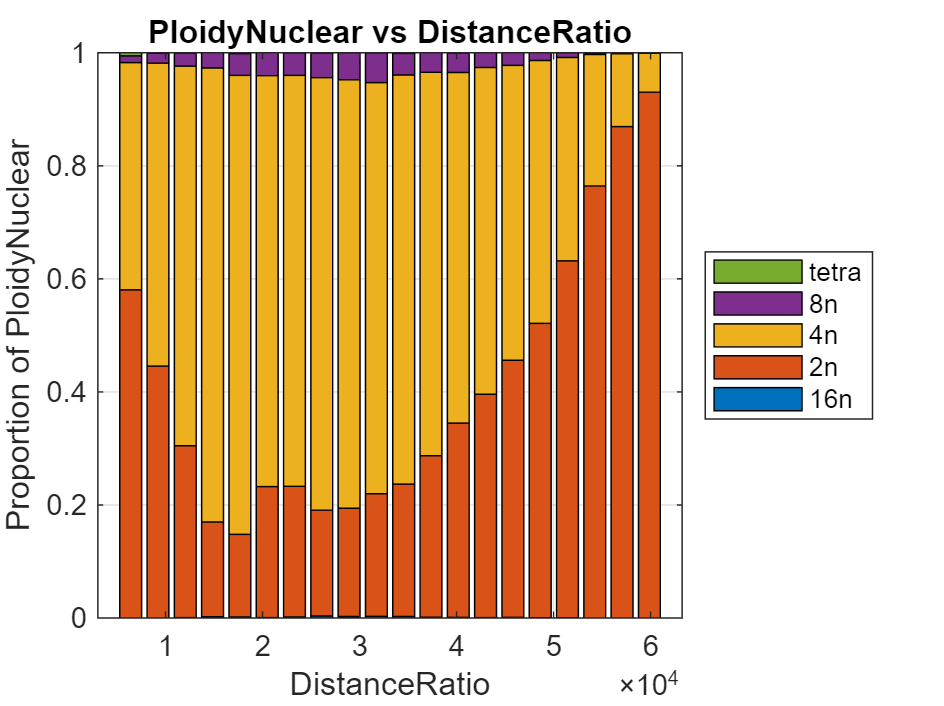

plot_stacked_proportions(table, columns2, 20);
saveas(gcf, 'nuclear ploidy.png')

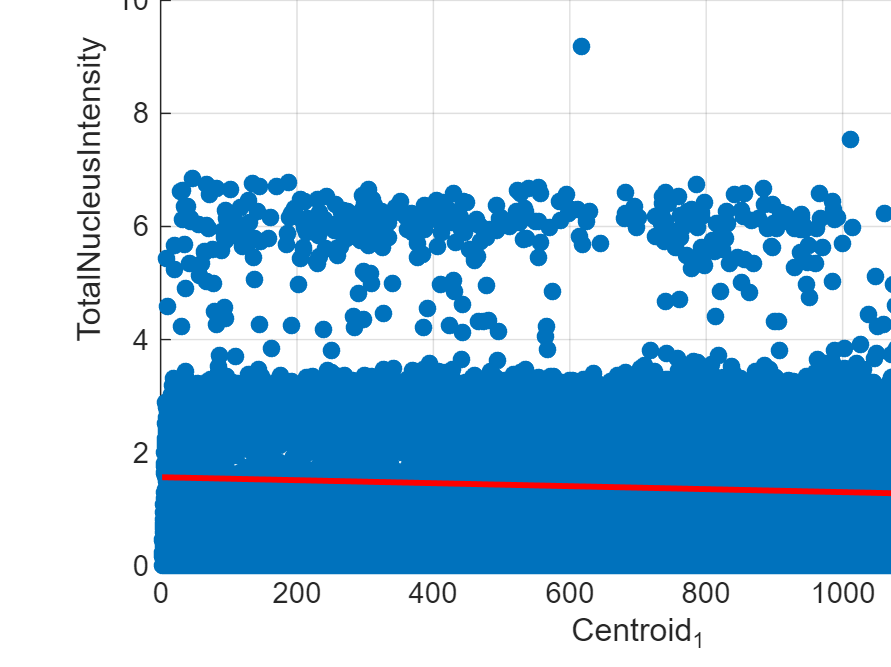

% ID, Centroid_1, Centroid_2, Centroid_3, Volume
% EigenValues_1, EigenValues_2, EigenValues_3
% TotalNucleusVolume, TotalNucleusIntensity, NumNuclei
% regionprops use xyz
temp_table = readtable(fullfile(folder, tempname));
columns3 = [10, 2];
plot_scatter(temp_table, columns3);

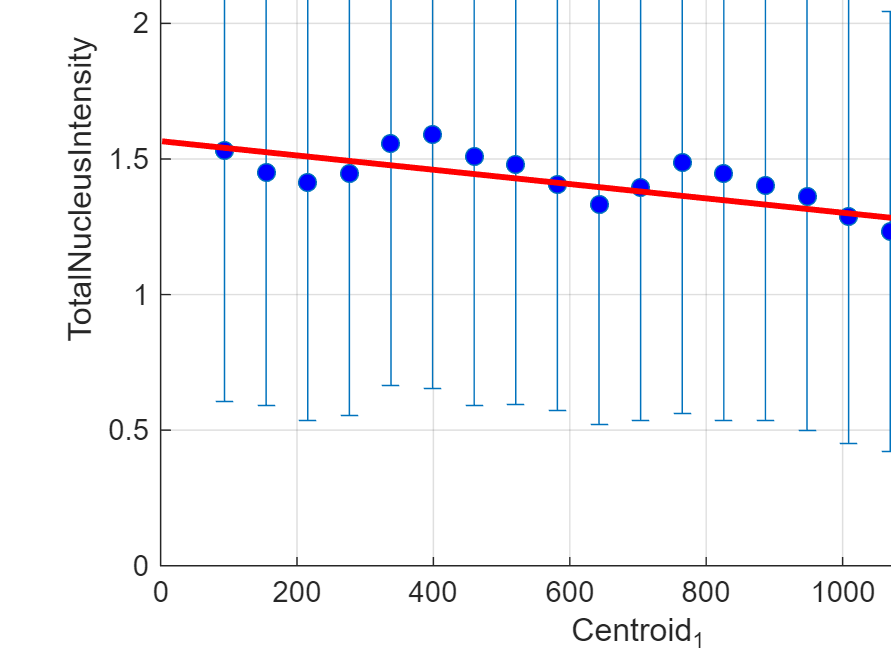

plot_error_bars(temp_table, columns3, 20);
saveas(gcf, 'x intensity.png')

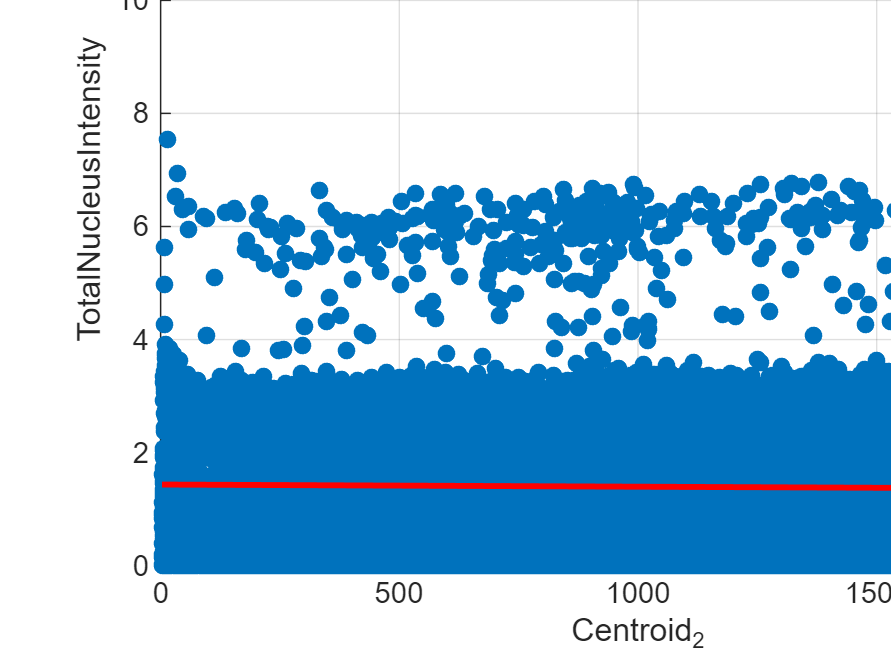


columns3 = [10, 3];
plot_scatter(temp_table, columns3);

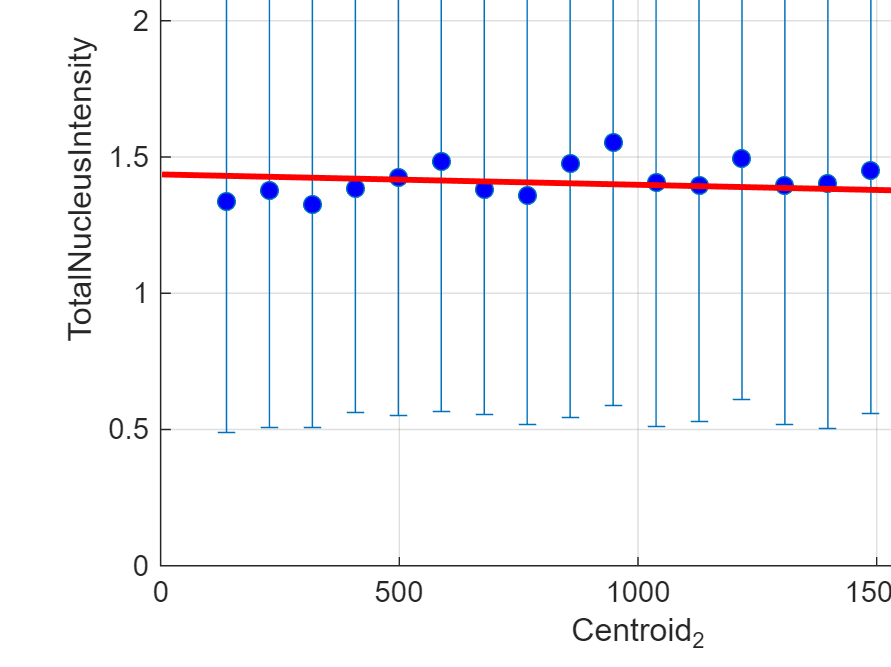

plot_error_bars(temp_table, columns3, 20);
saveas(gcf, 'y intensity.png')

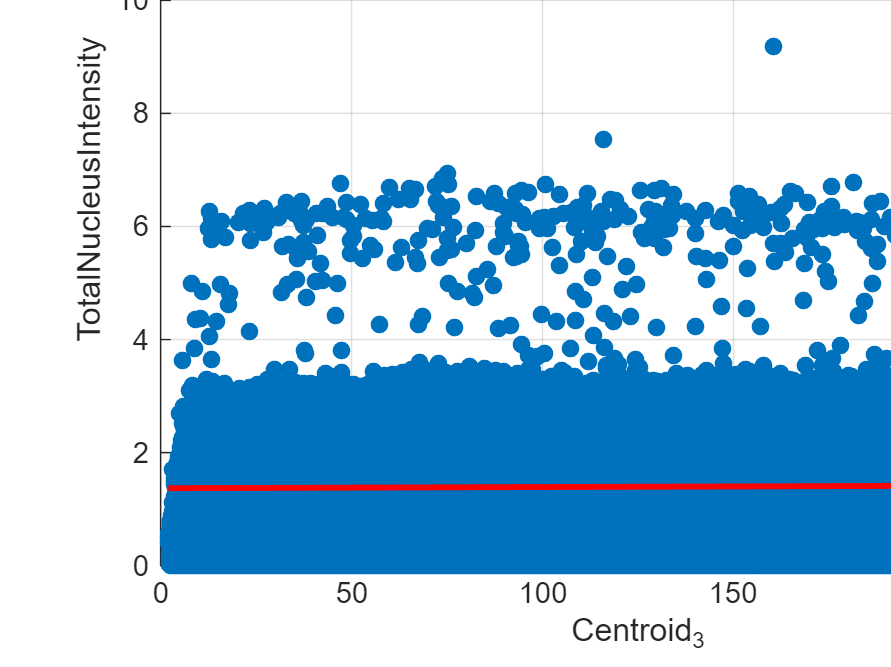


columns3 = [10, 4];
plot_scatter(temp_table, columns3);

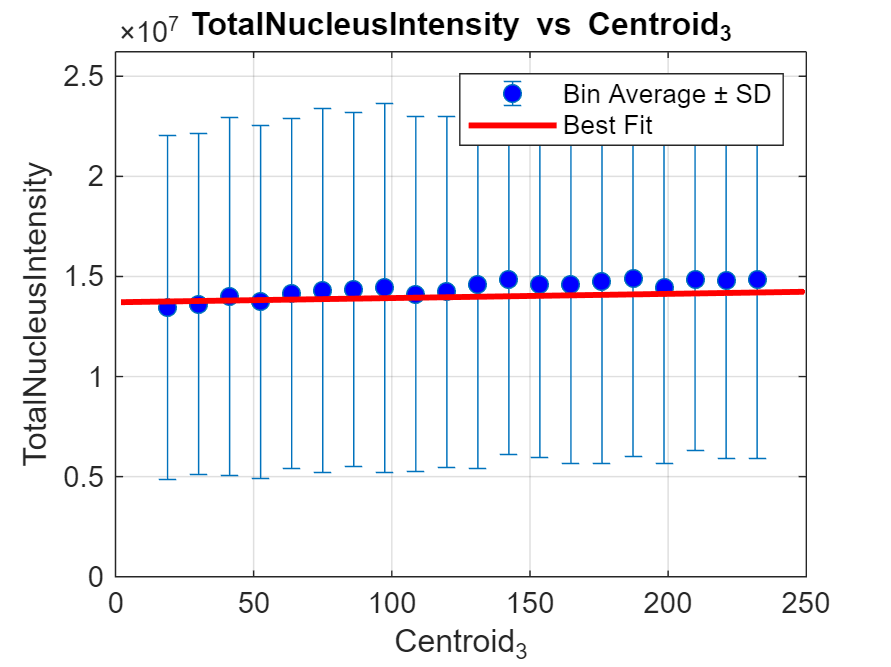

plot_error_bars(temp_table, columns3, 20);

saveas(gcf, 'z intensity.png')

% highlight polyploidy in image stack
table = readtable(fullfile(folder, outname));

multichannel = import4d(folder, imagename, extension, num_channel);

Finished importing channel 1
Finished importing channel 2
Finished importing channel 3
Finished importing channel 4


nucleus = multichannel(:, :, :, 1);
cellular = multichannel(:, :, :, 2);
cellular_mask = multichannel(:, :, :, 3);
nucleus_mask = multichannel(:, :, :, 4);

% For number of nuclei mapping
max_label = max(cellular_mask(:));
lookup1 = zeros(max_label + 1, 1, 'like', multichannel);
lookup1(table.ID + 1) = table.NumNuclei;
cellular_ploidy_image = lookup1(cellular_mask + 1);

% For all ploidy mapping
key1 = ["m2n", "m4n", "m8n", "m16n", "b2n", "b4n", "b8n", "b16n", "t2n", "t4n", "t8n", "tetra"];
d2 = dictionary(key1, 1:12);
lookup2 = zeros(max_label + 1, 1, 'like', multichannel);
lookup2(table.ID + 1) = d2(table.NuclearPloidy);
all_ploidy_image = lookup2(cellular_mask + 1);

% For nuclear ploidy mapping
key2 = ["2n", "4n", "8n", "16n", "tetra"];
d4 = dictionary(key2, 1:5);
lookup3 = zeros(max_label + 1, 1, 'like', multichannel);
lookup3(table.ID + 1) = d4(table.PloidyNuclear);
nuclear_ploidy_image = lookup3(cellular_mask + 1);

[y, x, z, c] = size(multichannel);
multichannel_new = zeros([y, x, z, 7], 'like', multichannel);
multichannel_new(:, :, :, 1) = nucleus;
multichannel_new(:, :, :, 2) = cellular;
multichannel_new(:, :, :, 3) = cellular_mask;
multichannel_new(:, :, :, 4) = nucleus_mask;
multichannel_new(:, :, :, 5) = cellular_ploidy_image;
multichannel_new(:, :, :, 6) = all_ploidy_image;
multichannel_new(:, :, :, 7) = nuclear_ploidy_image;
export4d_float32(multichannel_new, 7, folder, imageout, extension);